 
clear all
clc

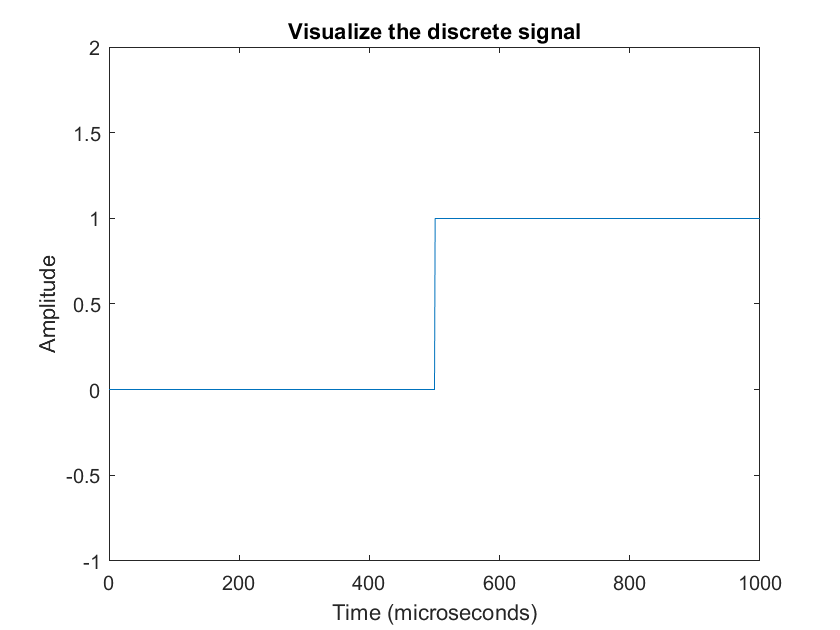


n = 0:1:1000; % Data Size

y = heaviside(n); 
Fs = (10^6)/2 ;  % Frquency in Hz
figure()
plot(y); 
axis([0 1000 -1 2]);
xlabel('Time (microseconds)')
ylabel('Amplitude')
title('Visualize the discrete signal')

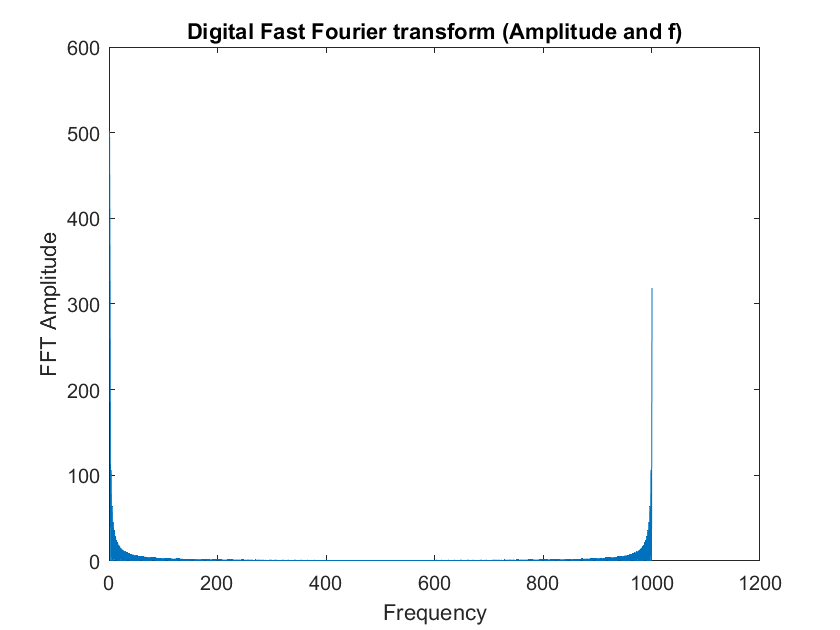


%% Digital Fast Fourier transform
x = (abs(fft(y)));   % FFT
figure()
plot(x)
hold on
xlabel('Frequency')
ylabel('FFT Amplitude')
title('Digital Fast Fourier transform (Amplitude and f)')


% -3dB bandwidth frequencies (f_low, f_high) in frequency spectrum.
[bw,flo,fhi] = powerbw(x)

bw = 0.0086

flo = 0

fhi = 0.0086


% Function for discrete signal x(k)

function y =heaviside(n);
y = 0*n;
y(find(n>= 500)) = 1;
end







